# Least Squares Support Vector Machines: Exercises, I

## Boris Shilov

First we set up the environment and load the LSSVM and SVM KU Leuven toolboxes by adding them to them path. Then set the seed for reproducible results.

rng('default')
rng(666)

## Two Gaussians

Two Gaussians with the same covariance matrix generate a dataset. Can we manually create something resembling an optimal classifier?

[X1, X2, Y1, Y2] = deal(randn(50, 2) + 1,  ...
    randn(51, 2) - 1, ones(50, 1), -ones(51, 1));
figure; hold on; plot(X1(:,1),X1(:,2), 'ro');
plot(X2(:,1),X2(:,2), 'bo'); hold off;

For binary classification, an optimal linear classifier classifies all of the data points correctly while being as far away from the points as possible. In this case, the data are not linearly separable, hence the first condition cannot be fulfilled. The linear classifier will have some inherent misclassification rate. The far-away-ness criterion is fulfilled by maximizing a margin around the line in which no points are present.

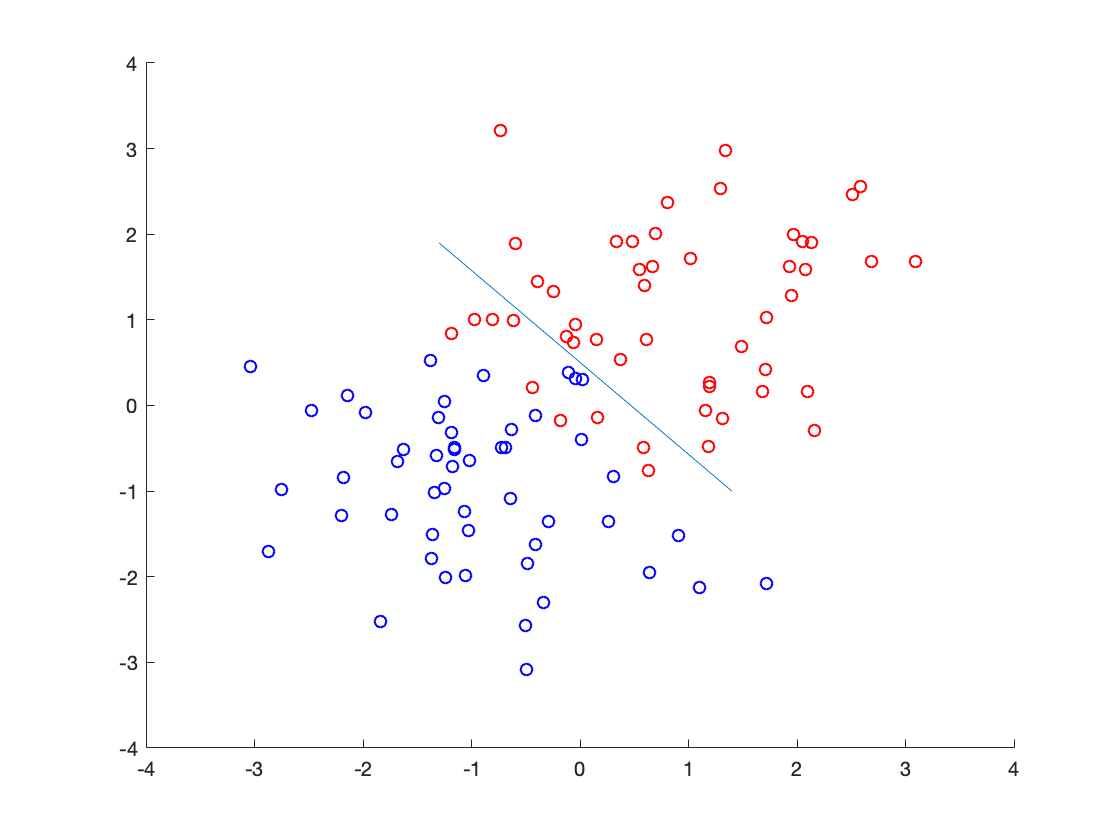

line([-1.3, 1.4], [1.9, -1])

## Support vector machine classifiers

Exploring the concept using the applet at [https://cs.stanford.edu/people/karpathy/svmjs/demo/.](https://cs.stanford.edu/people/karpathy/svmjs/demo/.)

### What is a support vector?

A support vector is a data point that lies closest to some hyperplane that is able to separate classes with no or minimal misclassification. These points define the margin of the hyperplane. The objective of the hyperplane is to separate the classes while at the same time minimizing the size of this margin. The margin itself is defined by the fact that, beyond the support vectors which lie on the boundary of the margin, there are no data points inside of it that are not support vectors. The contribution, or importance, of a particular point to the models' solution is determined by the computed weights.

### Linear kernel

Adding more points to the linear kernel adjusts the decision hyperplane slightly when adding outside the margin, and quite significantly when points are added outside the margin. How much a single point addition changes the boundary also depends on whether the point has been added close or far away from existing points of the same class.

The c parameter affects the number of support vectors used, and hence, the size of the margin. Below c = 1, the margin increases in size and the number of support vectors. This relationship is not so straightforward for larger values of c because the SVM converges around a number of vectors and stays there. This is in line with the fact that the c parameter is a measure of how much we want to avoid misclassification (how much the objective function takes misclassification into account).

The support vectors and their importances change with the value of c because in the dual formulation the weights of the data points cannot be more than c.

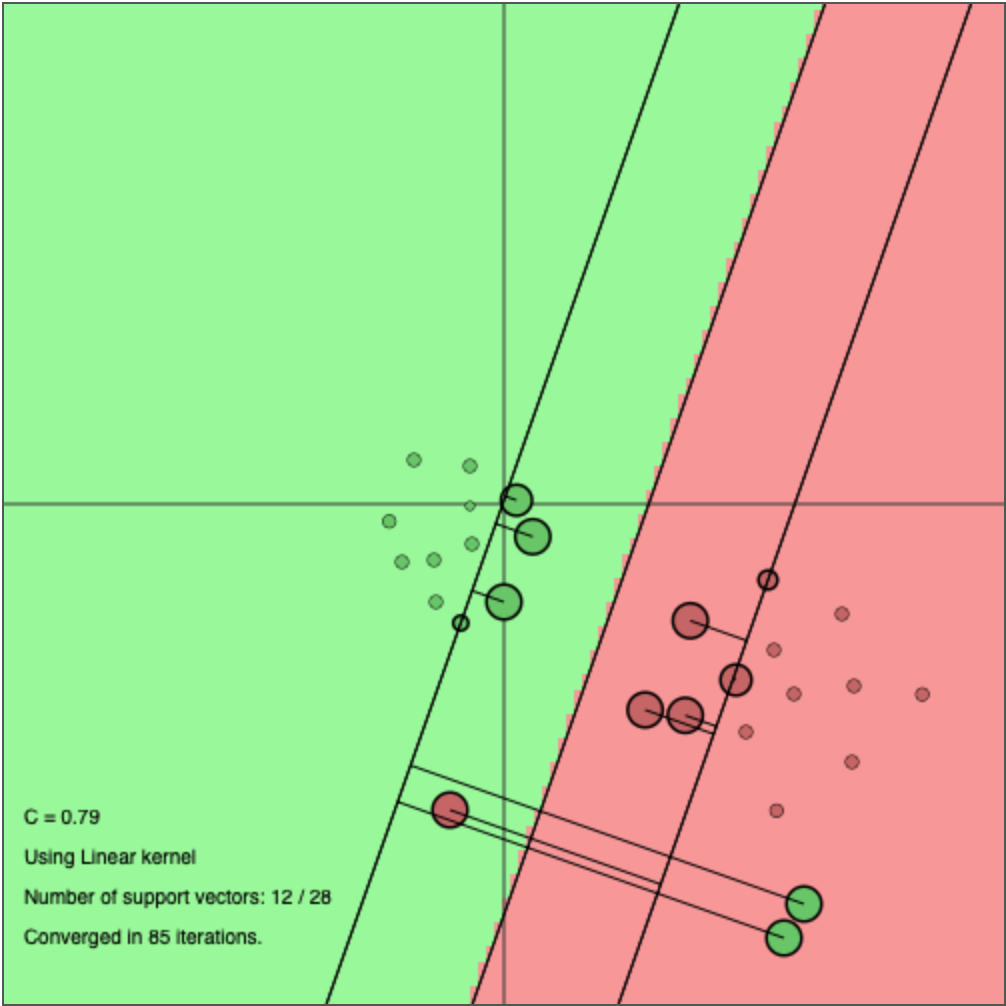

### RBF kernel

The RBF kernel gives us a nonlinear boundary. Here, additions of points even close to existing ones can have large effects on classification far outside the region, since the RBF kernel has to extrapolate classification in some way for the entire areas outside the point clouds - hence, adding more points can shift the area to be classed as one class or the other.

Varying c has a large effect on how classification is done but generally results in either the collapse of the decision boundary to individual points of one class or maintaining the general shape of the boundary. Varying the sigma parameter has a large effect, smaller values make the boundary more granular, again to the point of collapsing it around the individual points of one class. On the other hand, making sigma very large makes the boundary more and more linear. This is consistent with the fact that sigma determines how much influence a single data point has on the decision boundary - taking into account only a few values in the case of high sigma thus makes the boundary linear.

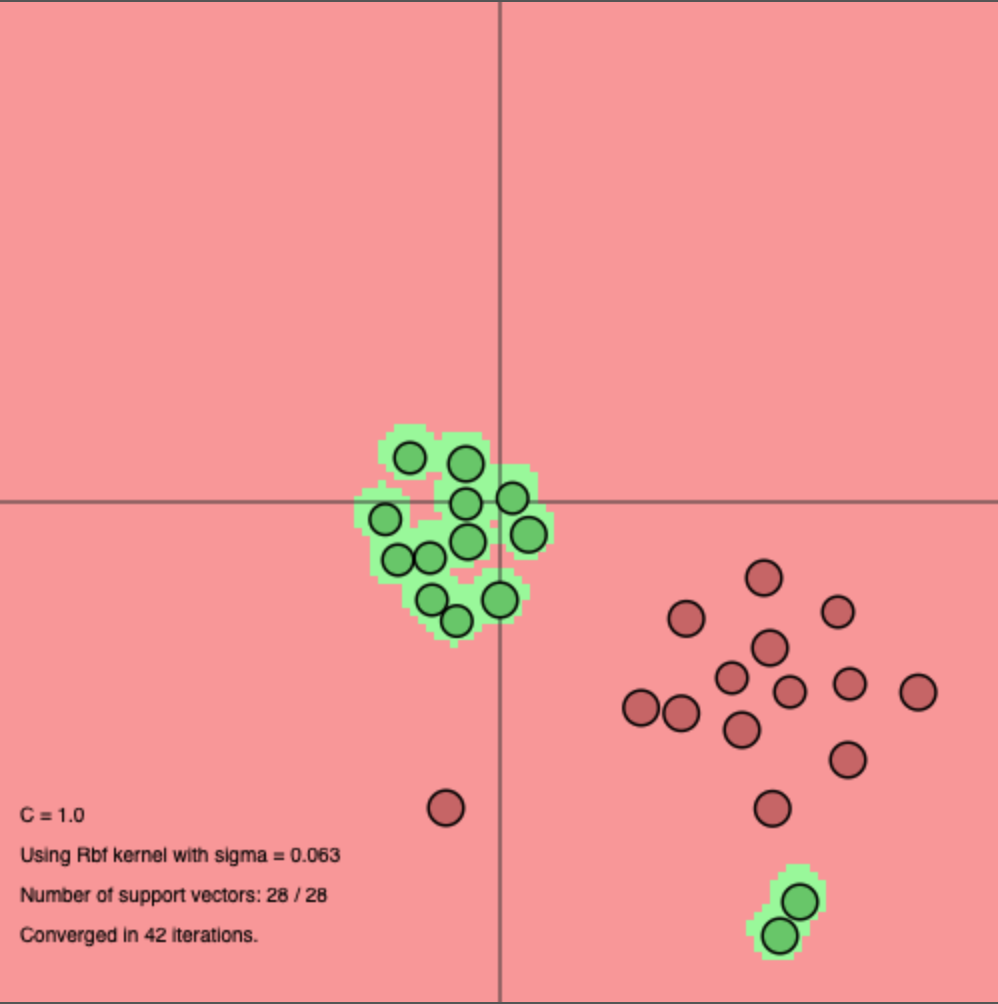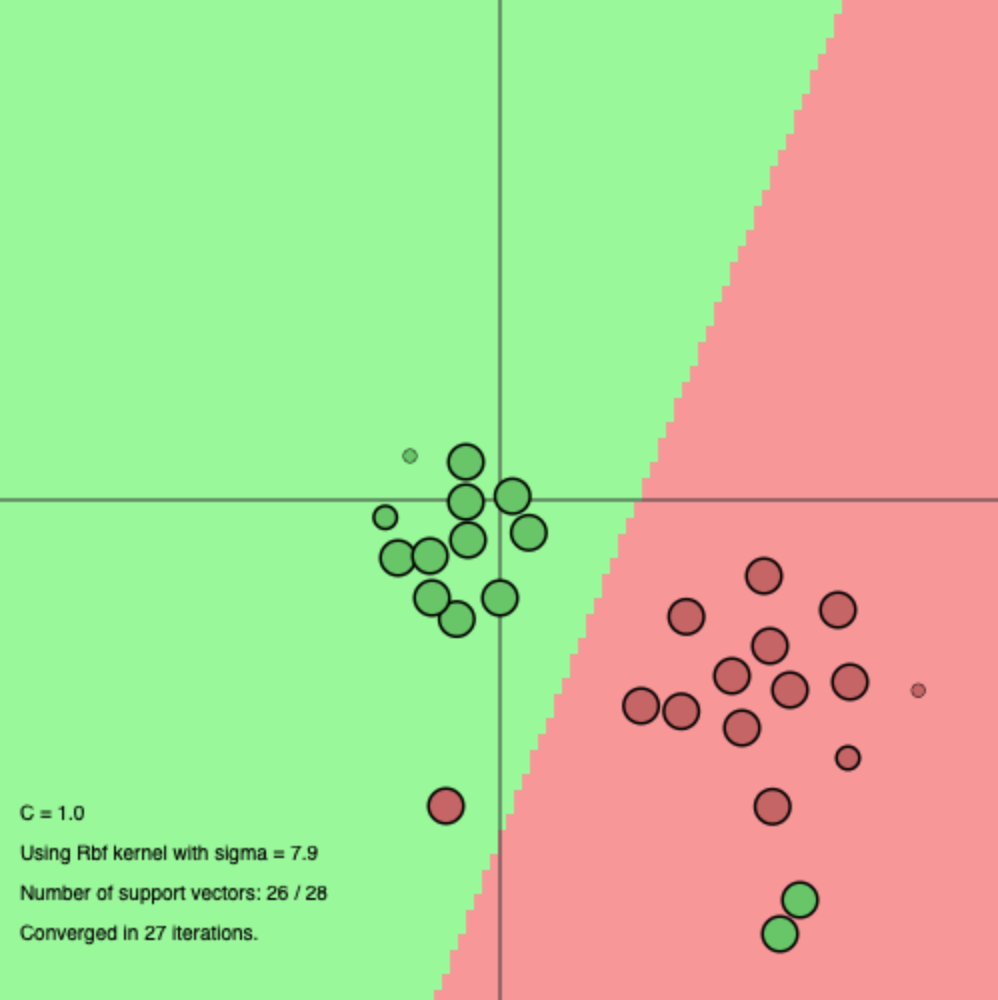

### Comparison between linear and RBF in this applet

It seems that linear kernel works extremely well in the case of separable or mostly separable data. The RBF kernel is more suitable in case of nonseparable data, since the decision boundary is extremely flexible and granular. 

## Least-squares support vector machine classifier - iris example

Load the iris dataset into Xtrain, Xtest, Ytrain, Ytest variables.

load iris.mat;

### Influence of hyperparameters and kernel parameters

#### Polynomial kernel

We can attempt modelling with polynomial kernels of different degrees, with $t=gam=1$.

gam = 1; degrees = {[1 1], [1 2], [1 3], [1 4], [1 5], [1 6]};
params = cellfun(@(degree) ...
    {Xtrain, Ytrain, 'c', gam, degree, 'poly_kernel'}, ...
    degrees, 'UniformOutput', false);
polyModels = cellfun(@(x) trainlssvm(x), params, ...
    'UniformOutput',false);

Now evaluate on test set.

polyModelSim = cellfun(@(model) simlssvm(...
    {model.xtrain, model.ytrain, model.type, model.gam, model.kernel_pars, model.kernel_type}, ...
    {model.alpha, model.b}, Xtest), polyModels,'UniformOutput', false);

We can now use evaluate the models by considering their misclasification rate.

polyPerf = cellfun(@(sim) ...
    [sum(sim ~= Ytest), sum(sim ~= Ytest)/length(Ytest)*100], polyModelSim, ...
    'UniformOutput', false);

The last three models have the same and lower misclassification rates.

We can also plot the decision boundary for one of them using the following function.

Start Plotting...

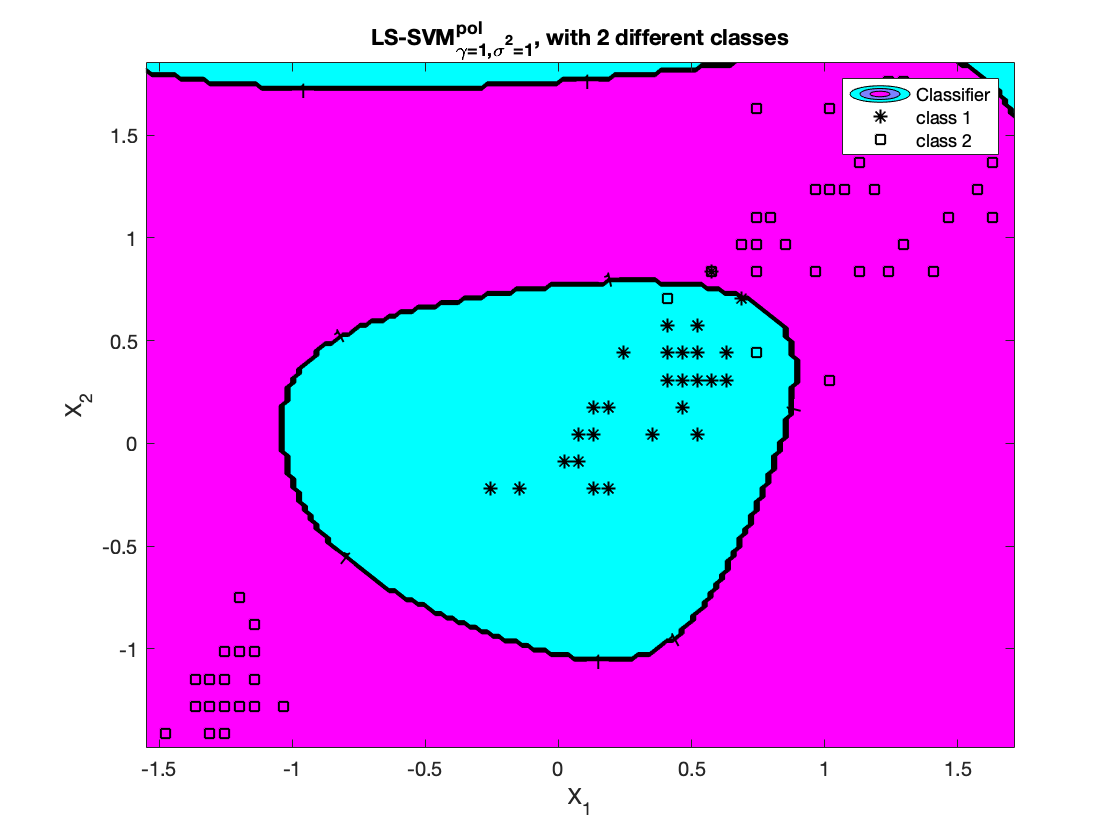

finished


ans = struct with fields:
           type: 'c'
          x_dim: 2
          y_dim: 1
        nb_data: 100
    kernel_type: 'poly_kernel'
     preprocess: 'preprocess'
      prestatus: 'ok'
         xtrain: [100×2 double]
         ytrain: [100×1 double]
       selector: [1×100 double]
            gam: 1
    kernel_pars: [1 5]
       x_delays: 0
       y_delays: 0
          steps: 1
         latent: 'no'
           code: 'original'
       codetype: 'none'
    pre_xscheme: 'cc'
    pre_yscheme: 'b'
      pre_xmean: [-1.6209e-16 -3.1086e-16]
       pre_xstd: [1.0000 1.0000]
      pre_ymean: -1
       pre_ystd: 1
         status: 'trained'
        weights: []
          alpha: [100×1 double]
              b: -1.1437


plotterPoly = @(model) plotlssvm({model.xtrain, model.ytrain, model.type, ...
    model.gam, model.kernel_pars, model.kernel_type}, {
model.alpha, model.b});
plotterPoly(polyModels{5})

This decision boundary is quite reasonable.

#### RBF kernel

We can try a range of sigma parameters to find a well performing RBF kernel model.

gam = 1; sigmas = [0.001, 0.005, 0.01, 0.1, 1, 2, 10, 30, 50, 100];
RBFParams = arrayfun(@(sigma) {Xtrain, Ytrain, 'c', gam, sigma,'RBF_kernel'}, ...
    sigmas, 'UniformOutput', false);
RBFModels = cellfun(@(param) trainlssvm(param), ...
    RBFParams, 'UniformOutput',false);
RBFModelSim = cellfun(@(model) simlssvm({model.xtrain, model.ytrain, model.type, ...
    model.gam, model.kernel_pars, model.kernel_type}, ...
    {model.alpha, model.b}, Xtest), RBFModels,'UniformOutput', false);
RBFPerf = cellfun(@(sim) [sum(sim ~= Ytest), sum(sim ~= Ytest)/length(Ytest)*100], ...
    RBFModelSim, 'UniformOutput', false);

It seems that none of the sigma choices perform particularly well on this dataset, but the middle ranges chosen are worse than the start and end values. Based on the plotted decision surfaces, a sigma value of 0.01 seems quite reasonable.

We can do the same comparison with a range of gam parameters.

sigma = 0.01; gams = [0.1, 1, 2, 5, 10, 30, 50, 100];
RBFParamsG = arrayfun(@(gamPar) {Xtrain, Ytrain, 'c', gamPar, sigma,'RBF_kernel'}, ...
    gams, 'UniformOutput', false);
RBFModelsG = cellfun(@(param) trainlssvm(param), ...
    RBFParamsG, 'UniformOutput', false);
RBFModelSimG = cellfun(@(model) simlssvm({model.xtrain, model.ytrain, model.type, ...
    model.gam, model.kernel_pars, model.kernel_type}, ...
    {model.alpha, model.b}, Xtest), RBFModelsG, 'UniformOutput', false);
RBFPerfG = cellfun(@(sim) [sum(sim ~= Ytest), ...
    sum(sim ~= Ytest)/length(Ytest)*100], RBFModelSimG, 'UniformOutput', false);

Let us plot one of the resulting models.

Start Plotting...

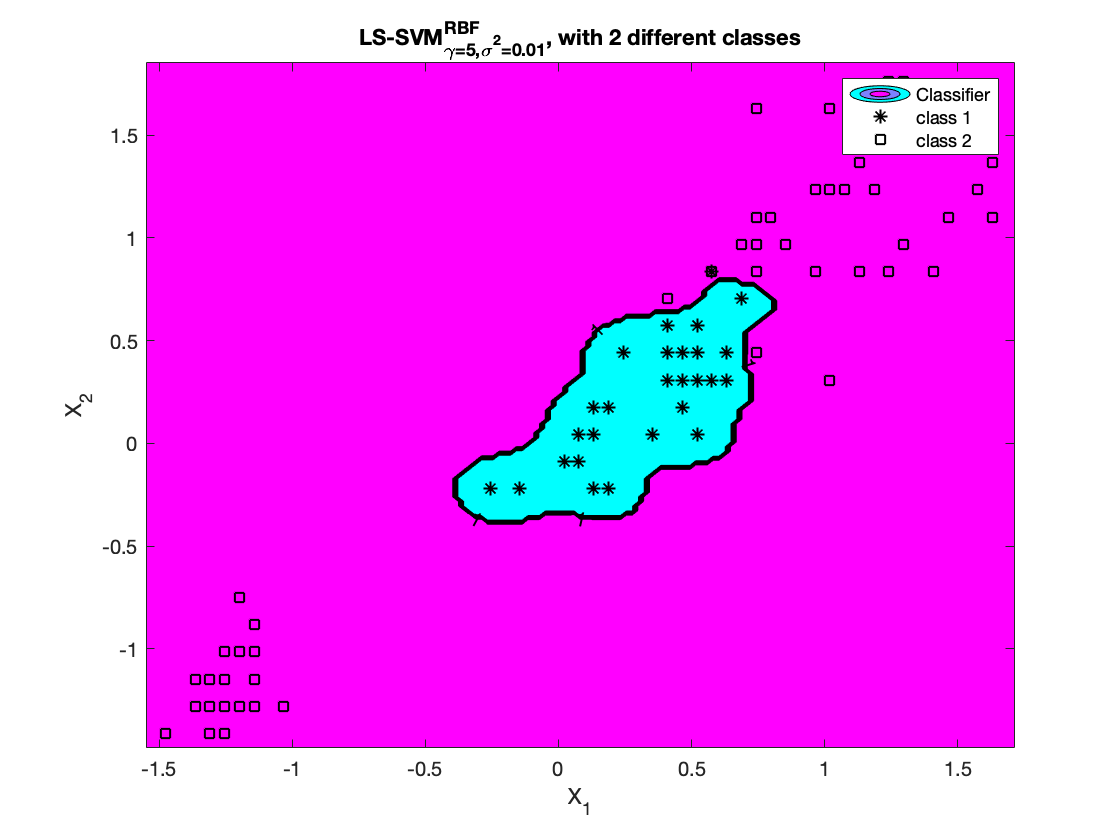

finished


ans = struct with fields:
           type: 'c'
          x_dim: 2
          y_dim: 1
        nb_data: 100
    kernel_type: 'RBF_kernel'
     preprocess: 'preprocess'
      prestatus: 'ok'
         xtrain: [100×2 double]
         ytrain: [100×1 double]
       selector: [1×100 double]
            gam: 5
    kernel_pars: 0.0100
       x_delays: 0
       y_delays: 0
          steps: 1
         latent: 'no'
           code: 'original'
       codetype: 'none'
    pre_xscheme: 'cc'
    pre_yscheme: 'b'
      pre_xmean: [-1.6209e-16 -3.1086e-16]
       pre_xstd: [1.0000 1.0000]
      pre_ymean: -1
       pre_ystd: 1
         status: 'trained'
        weights: []
          alpha: [100×1 double]
              b: 0.3734


plotterRBF = @(model) plotlssvm({model.xtrain, model.ytrain, model.type, ...
    model.gam, model.kernel_pars, model.kernel_type}, {
model.alpha, model.b});
plotterRBF(RBFModelsG{4})

These results are broadly similar to the sample script provided.

### Tuning parameters using validation

We can look at the performance of different validaton methods in parameter tuning: random splits, k-fold and leave-one-out cross validation. We will do this for the RBF kernel.

First we create the range of parameters to walk over.

gams = 10e-3:10e2:10e3; sigmas = 10e-3:10e2:10e3;
[sigmasMesh, gamsMesh] = meshgrid(sigmas, gams);
parameterSpace = num2cell([gamsMesh(:), sigmasMesh(:)], 2);

#### Random split

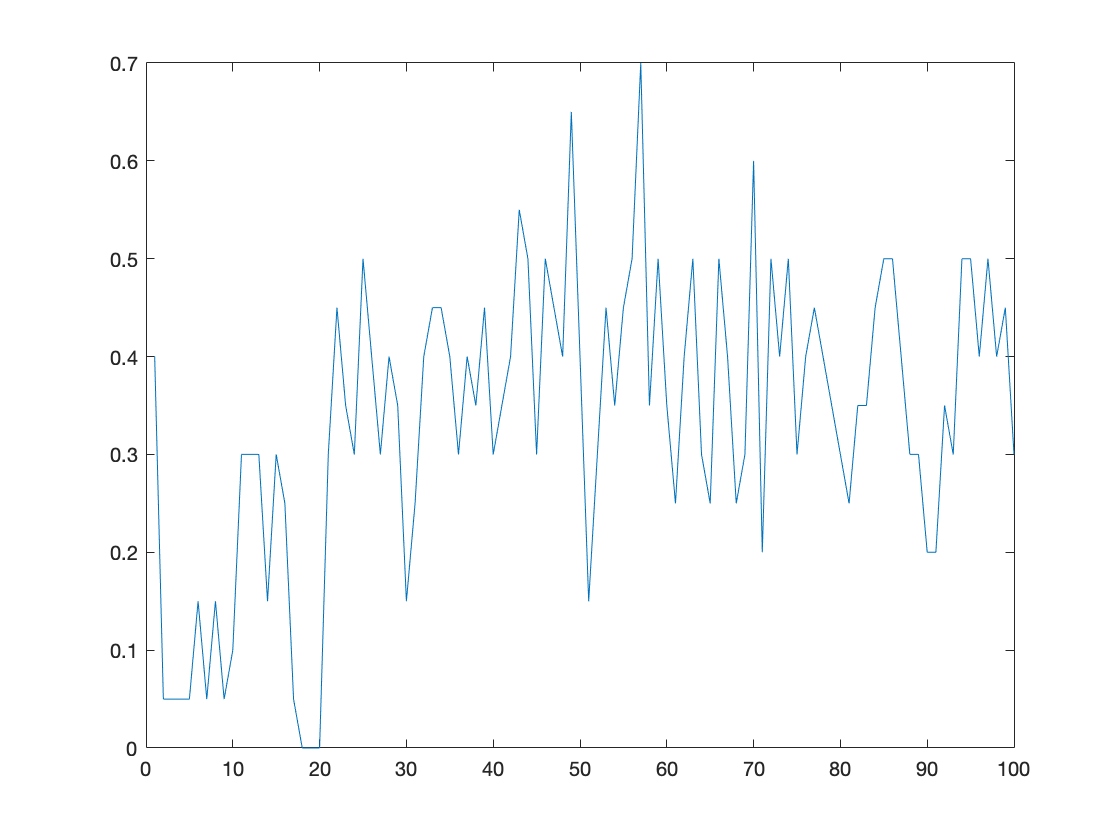

randomPerfList = cellfun(@(cell) rsplitvalidate({ Xtrain , Ytrain , 'c', ...
    cell(:, 1), cell(:, 2), 'RBF_kernel'}, 0.80,'misclass'), parameterSpace);
plot(randomPerfList)

#### k-fold cross validation

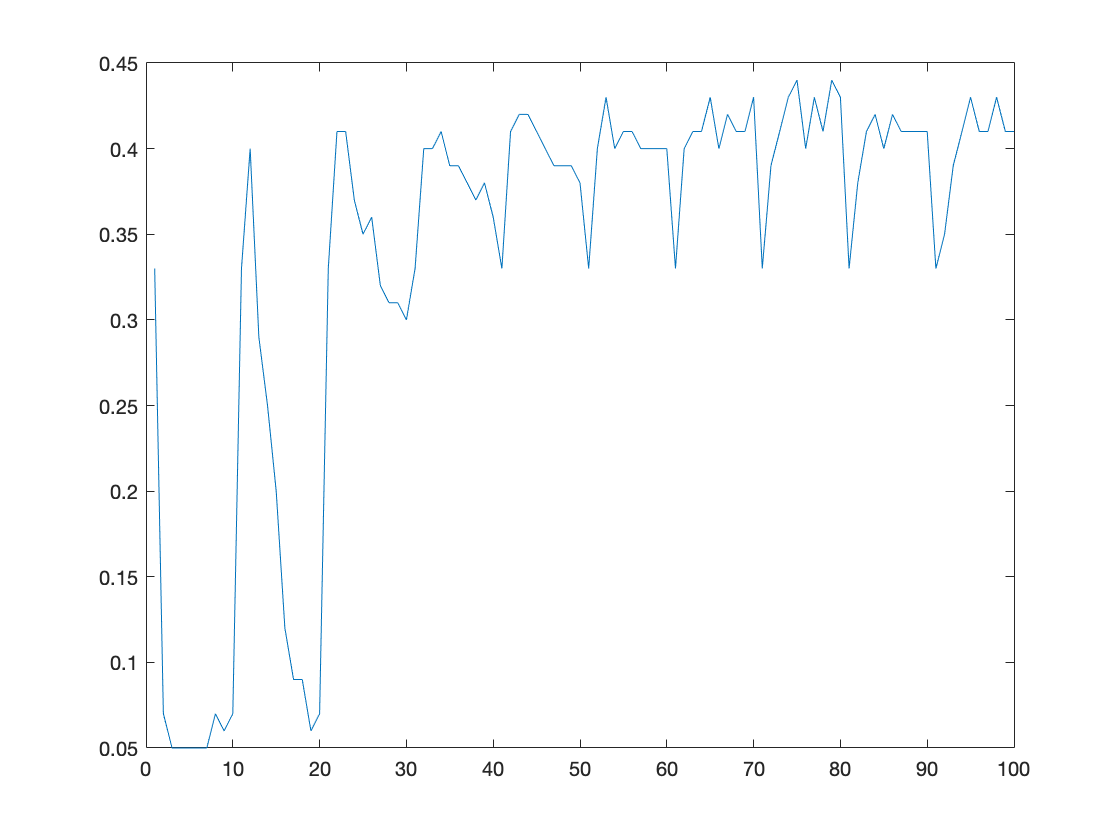

tenFoldPerfList = cellfun(@(cell) crossvalidate({ Xtrain , Ytrain , 'c', ...
    cell(:, 1), cell(:, 2), 'RBF_kernel'}, 10,'misclass'), parameterSpace);
plot(tenFoldPerfList)

#### Leave-one-out cross validation

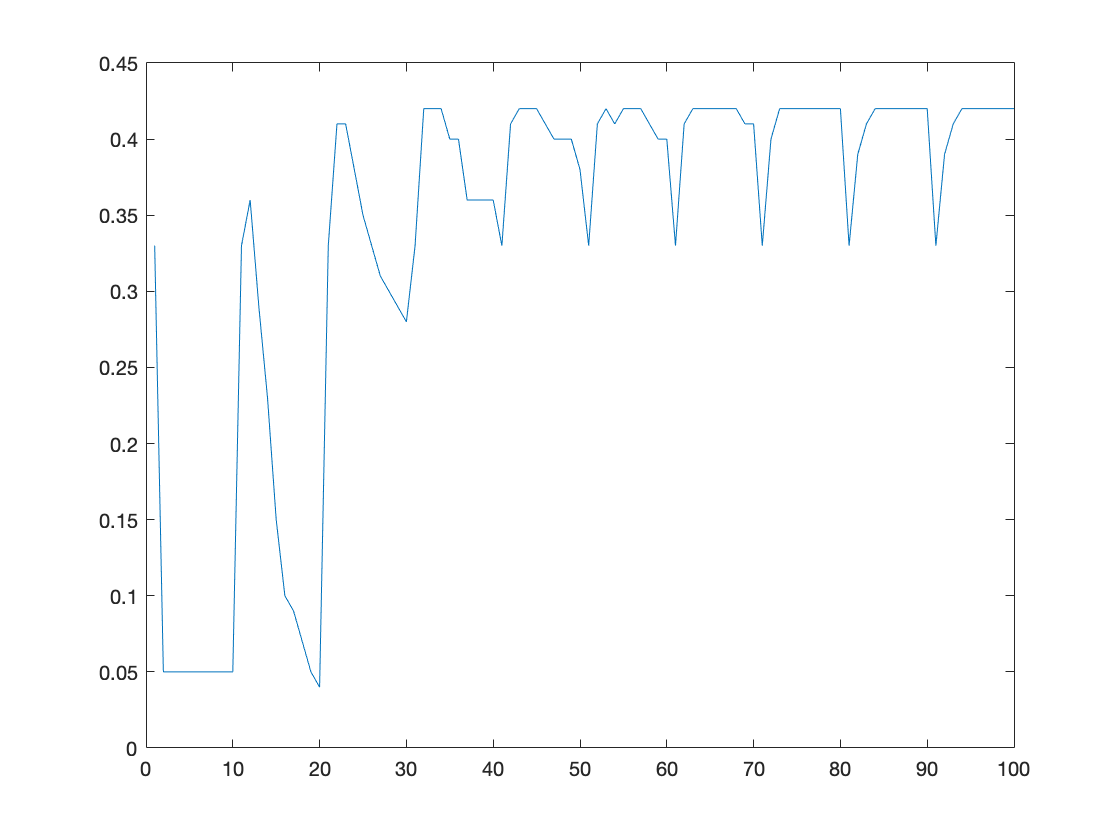

leaveOnePerfList = cellfun(@(cell) leaveoneout({ Xtrain , Ytrain , 'c', ...
    cell(:, 1), cell(:, 2), 'RBF_kernel'}, 'misclass'), parameterSpace);
plot(leaveOnePerfList)

All of the methods converge on the parameter values indexed 2nd-9th as quite adequate, as well as the 20th combination. It is clear that k-fold and LOOCV are much more stable. The 20th indexed combination is notable because it is very stable across all of these methods; we choose these parameters for that reason.

parameterSpace{20}

ans = 	1.0e+03 *

    9.0000    1.0000


Cross validation is generally more preferable than random splitting because it generalises better. There are usually computational shortcuts available to efficiently compute LOOCV for many methods, which makes it almost as practical as simple splitting. For k-fold, finding a good value of k is key. LOOCV is simply k-fold with k=n in theory, although the above mentioned computational shortcuts make the implementations different in practice. Generally, we attempt to choose the k so that the individual splits are representative of the whole dataset in the statistical sense. More specifically and practically, k has to be chosen by taking the bias-variance tradeoff into account, finding the minimum of the BV curve. James Gareth in his work "Introduction to Statistical Learning" suggests that values of k between 5 and 10 have been shown to be adequate for many datasets in this regard.

### Automatic parameter tuning

We can try doing parameter tuning using grid search or the Nelder-Mead downhill simplex methods.

[gamSimp, sigSimp, costSimp] = tunelssvm({Xtrain, Ytrain, 'c', ...
    [], [], 'RBF_kernel'}, 'simplex', 'crossvalidatelssvm', {10, 'misclass'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.0024
                                          [sig2]        0.092078
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2.0024    0.092078

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     4.000000e-02     1.8944        -2.3851      initial 
     2           5     4.000000e-02     1.8944        -2.3851      contract inside 
optimisation terminated sucessfully (TolFun criterion)

Simplex results: 
X=6.648277   0.092078, F(X)=4.000000e-02 

Obtained hyper-paramete

[gamBrute, sigBrute, costBrute] = tunelssvm({Xtrain, Ytrain, 'c', ...
    [], [], 'RBF_kernel'}, 'gridsearch', 'crossvalidatelssvm', {10, 'misclass'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.2204
                                          [sig2]        2.6655
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.060759      0.2188
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         0.06075923      181.1207
                          [sig2]        0.218797      32.4723
 
OPTIMIZATION IN LOG SCALE...


grain = 7

FIRST ITERATION:
   X=-2.8008     -1.5196 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.9136, X=-0.90067     -1.2932 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.4063      0.2744


Simplex method appears to give results closer to our previous observations that values of sigma close to 0 give good performance. It also gives us a gam value in the same range as we saw with the first ten indices before.

By contrast, the gridsearch method gives us a good sigma value, but a gam value that is far too close to the first index, which has shown not very good performance in all of our previous validation runs.

Both of these methods attempt to explore a multidimensional space and converge on the objective function minimum. 

The grid search approach is a brute force approach of generating a matrix of parameter values to try, hence it is in a way a discretisation of this space. Since every value has to be tried this is computationally heavy and we are not guaranteed to find any minimum at all if the specified intervals are too coarse, at least in the continuous objective function sense. Hence unless we are lucky and obtain a good interval the cost of the optimal parameters will generally be in the neighbourhood of some local minimum, but not quite there.

The Nelder-Mead method uses a simplex with random (or rather, in the case of the LS-SVM package, found by simulated annealing) vertices. An n-dimensional simplex is formed by n+1 points not lying in the same plane. At each step in this method the objective function is evaluated at each of its vertices to obtain a ranking, and depending on the result, one of four operations are performed on the simplex that modify it, hopefully resulting in a simplex closer to some local minimum. Eventually some convergence criterion is reached and the method returns the resulting best vertex value. This is very efficient, but is very sensitive to starting coordinates. One other advantage is that whatever minimum NM zeroes in on will be the local minimum value for that neighbourhood.

We need to reset the RNG after using these methods.

rng('default')
rng(666)

### Receiver Operating Characteristic curves

A very popular way to judge binary classifier quality are ROC curves. Since we are specifically interested in how good the model is at predicting unobserved data, this is computed on the test set which we have not really used up until now. We can use the Nelder-Mead hyperparameter model we obtained previously that we are relatively confident in.

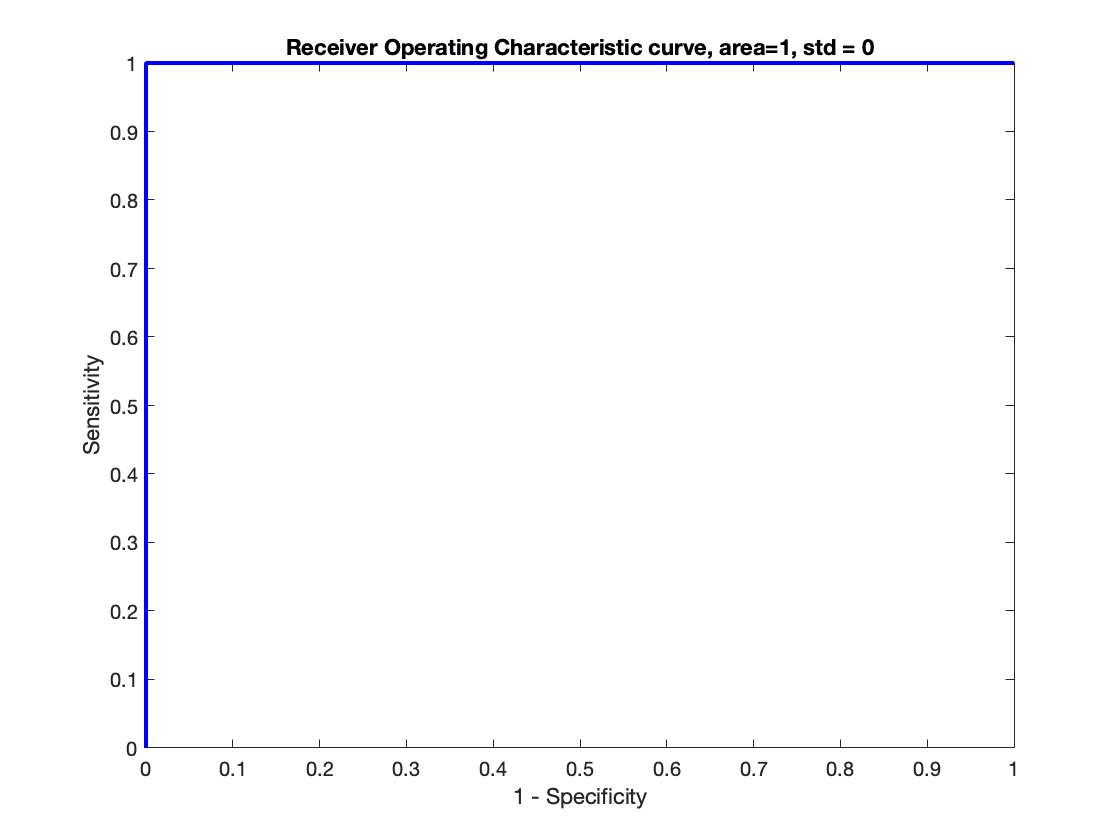

ans = 1

finModel = {Xtrain, Ytrain, 'c', gamSimp, sigSimp, 'RBF_kernel'};
finParams = trainlssvm(finModel);
[Yest, Ylatent] = simlssvm(finModel, {finParams.alpha, finParams.b}, Xtest);
roc(Ylatent, Ytest)

Normally a perfect ROC with area equals one would be indicative of using a non-independent test set. However, if we visualise the train and test data, it can be easily seen that the test data indeed falls perfectly into the classification regions provided by this model.

### Posterior class probability estimation via Bayes

We can calculate the probability that a given point is part of a given class.

 COMPUTING PLOT OF MODERATED OUTPUT


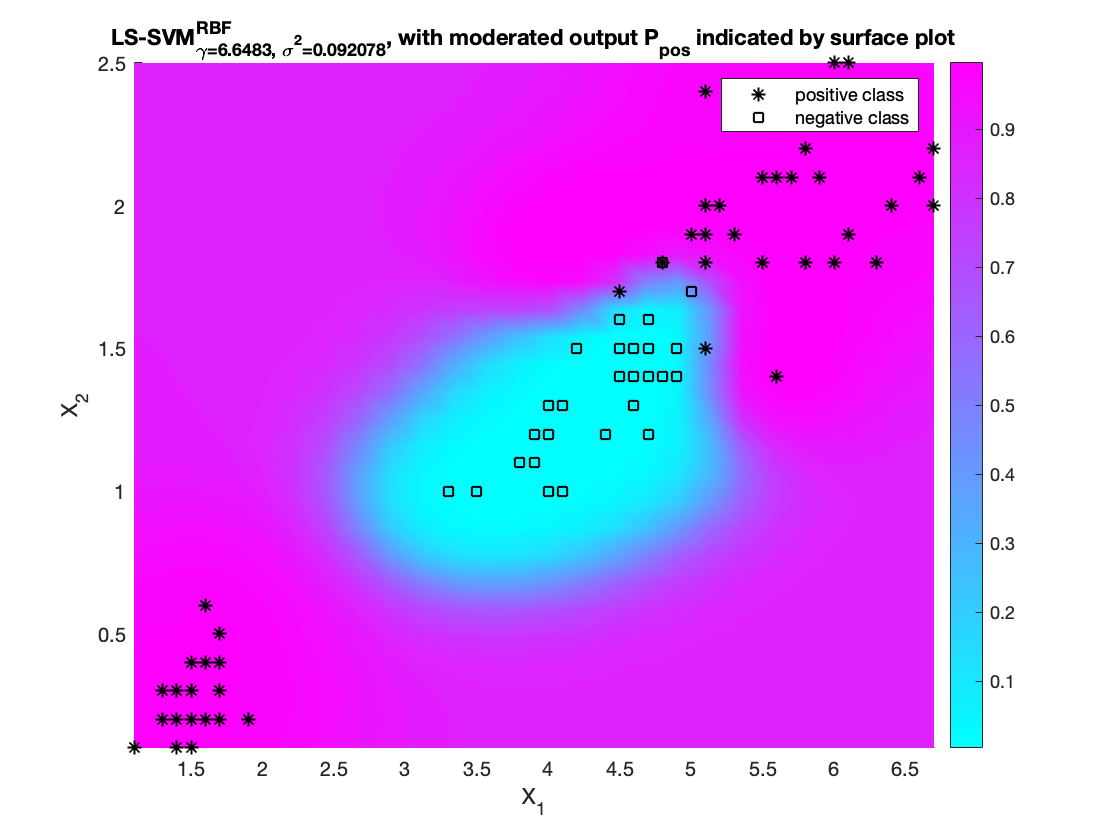

bay_modoutClass(finModel, 'figure'); colorbar;

This is an excellent way to reduce unnecessary dichotomisation associated with SVMs, stemming from the decision boundary approach. Areas that are devoid of data points are clearly marked as basically random chance by this Bayesian estimation method. Whereas using SVMs normally allows us to make clear cut decisions - very useful in a clinical setting, for example - the Bayesian approach gives us a way to see the uncertainty.

The Bayesian method still reflects the underlying model, however. We can apply this to a  previously visualised model to see that.

 COMPUTING PLOT OF MODERATED OUTPUT


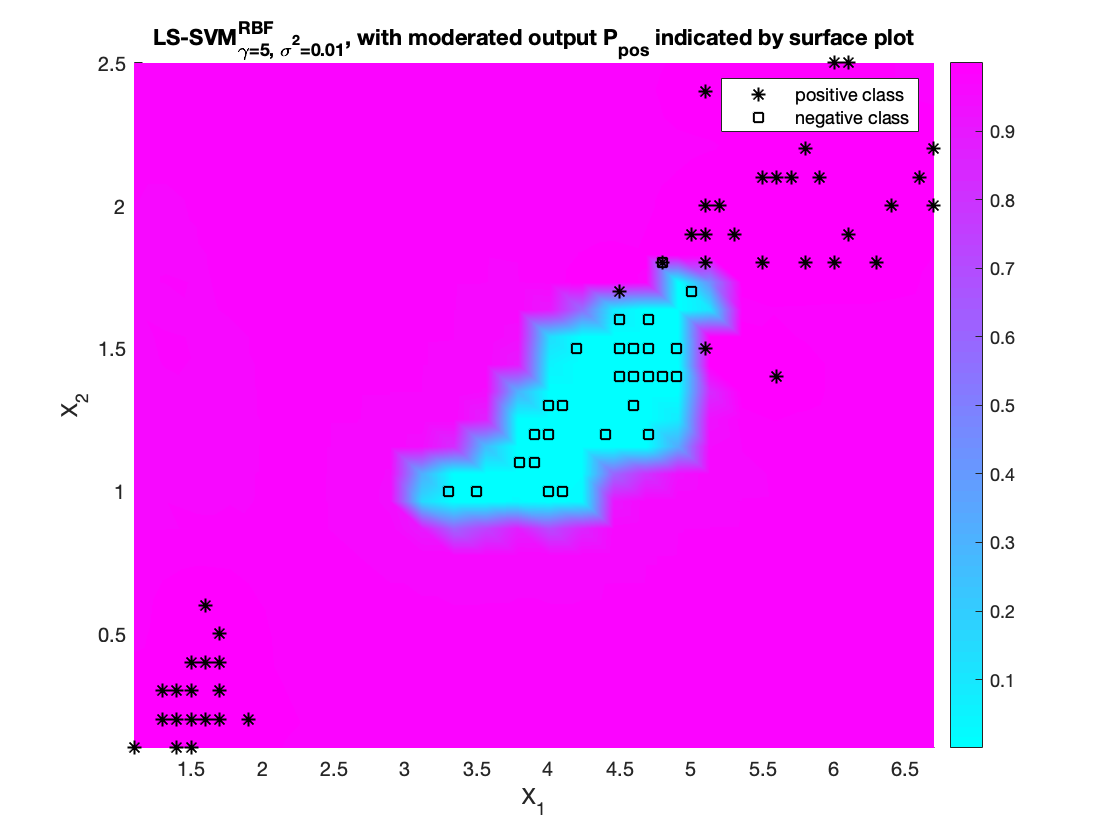

bay_modoutClass(RBFModelsG{4}, 'figure'); colorbar;

We can also see what happens if we change the parameters. For example, if we used the grid search values:

 COMPUTING PLOT OF MODERATED OUTPUT


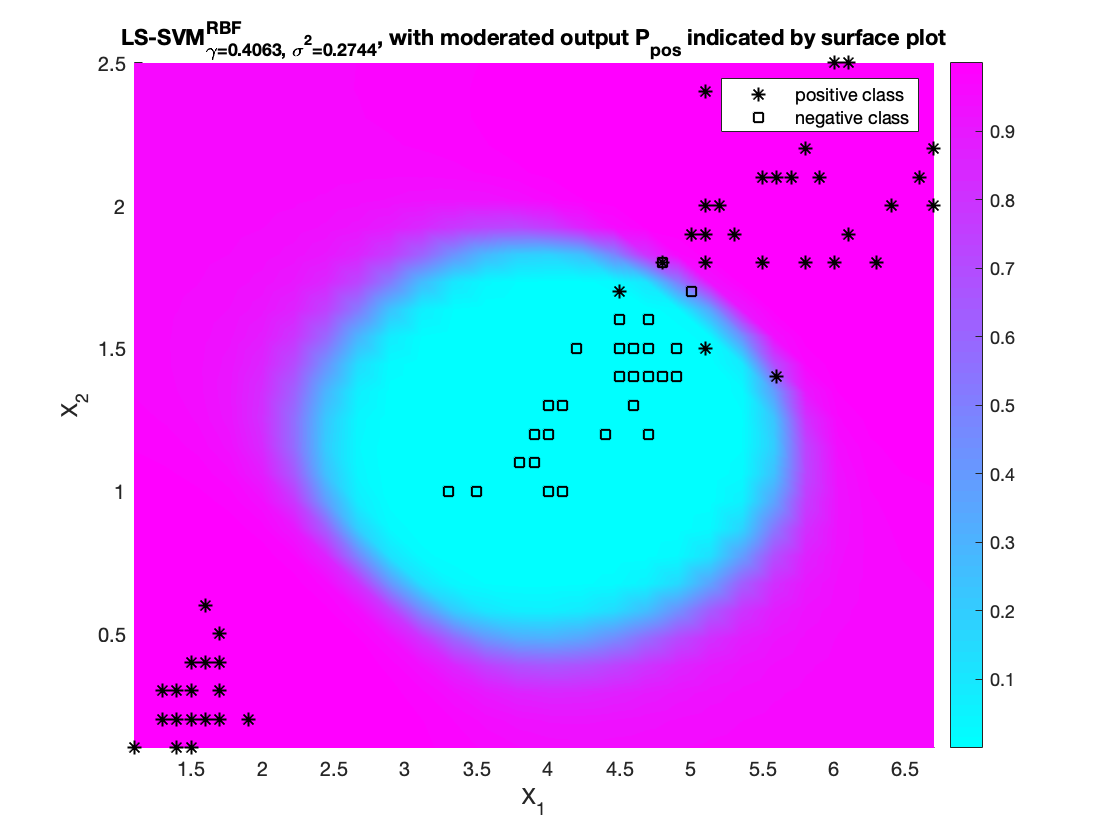

brutModel = {Xtrain, Ytrain, 'c', gamBrute, sigBrute, 'RBF_kernel'};
figure;
bay_modoutClass(brutModel, 'figure'); colorbar;

It is clear that some models have more uncertainty than others.

## LS-SVM classifier - ripley example

First we define some accessory functions that will come in handy to reduce code duplication. These are listed at the end of this report due to the technical limitations of Matlab.

Load the dataset.

ripleyDat = load('ripley.mat');

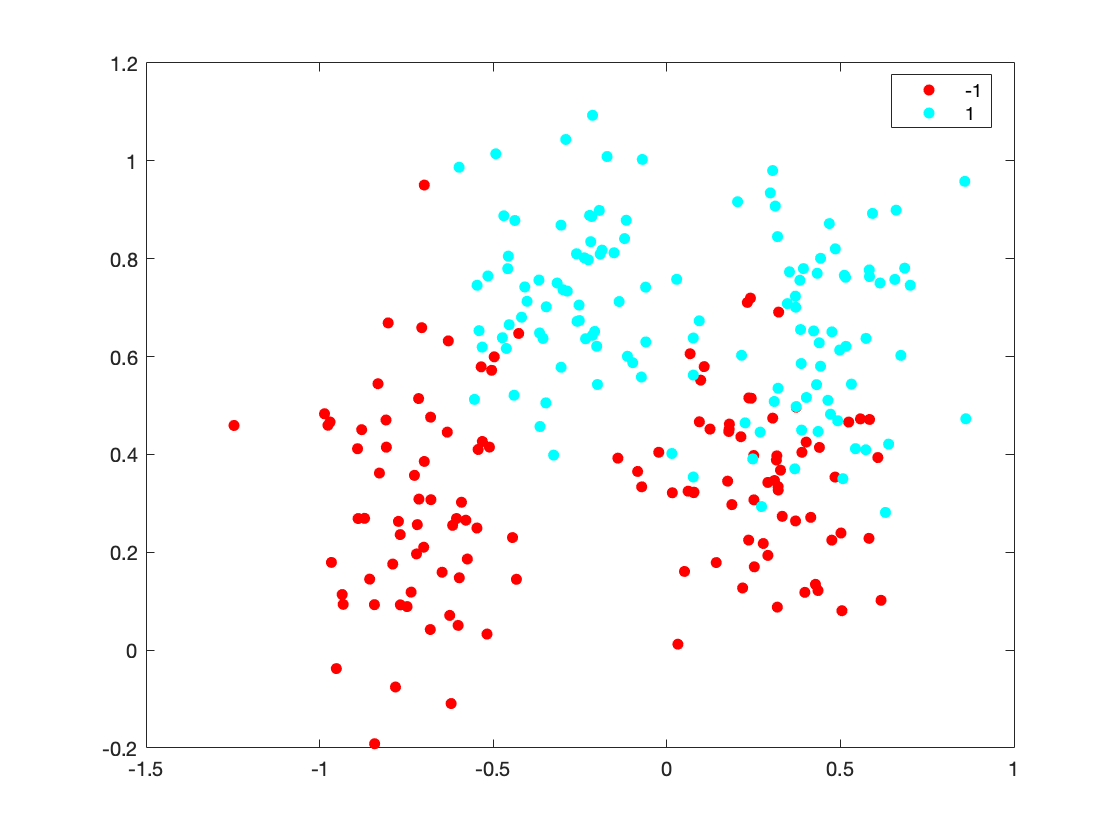

figure;
gscatter(ripleyDat.Xtrain(:, 1), ripleyDat.Xtrain(:, 2), ripleyDat.Ytrain)

This is a mixture of two Gaussian distributions and is clearly not linearly separable. Thus we will have to operate on a higher dimensional feature space instead of the input space - using an RBF kernel, for example. A polynomial kernel could also be suitable.

[ripleyModel, ripleyYest, ripleyYlatent] = RBFModelBuilder(ripleyDat.Xtrain, ripleyDat.Ytrain, ripleyDat.Xtest);


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.7522
                                          [sig2]        0.51332
                                          F(X)=         0.124
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2.7522     0.51332

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     1.240000e-01     1.0124        -0.6669      initial 
     2           4     1.240000e-01     1.0124        -0.6669      reflect 
     3           6     1.240000e-01     1.0124        -0.6669      contract outside 
     4          10     1.240000e-01     1.0124        -0.6669  

Start Plotting...

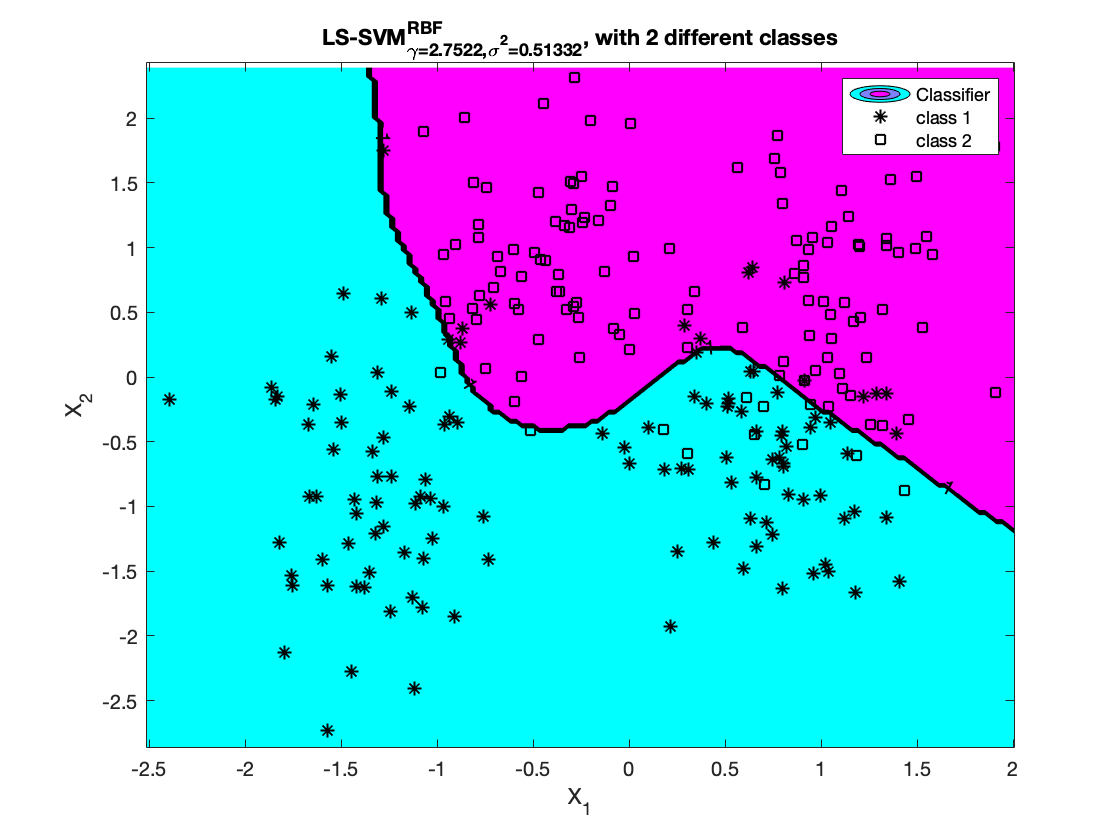

finished


plotlssvm({ripleyModel.xtrain, ripleyModel.ytrain, ripleyModel.type, ...
    ripleyModel.gam, ripleyModel.kernel_pars, ripleyModel.kernel_type}, {ripleyModel.alpha, ripleyModel.b});

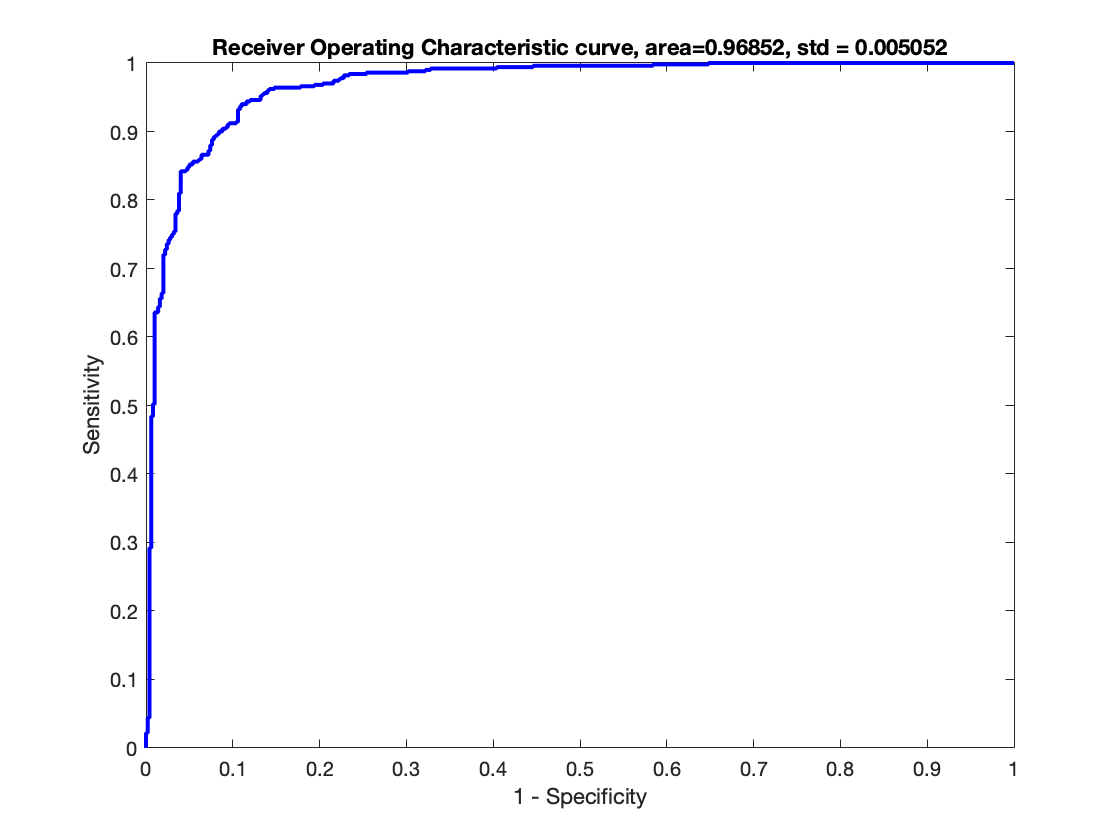

ans = 0.9685

roc(ripleyYlatent, ripleyDat.Ytest)

This RBF model appears to be a very good model for this task. 

## LS-SVM classifier - Wisconsin breast cancer example

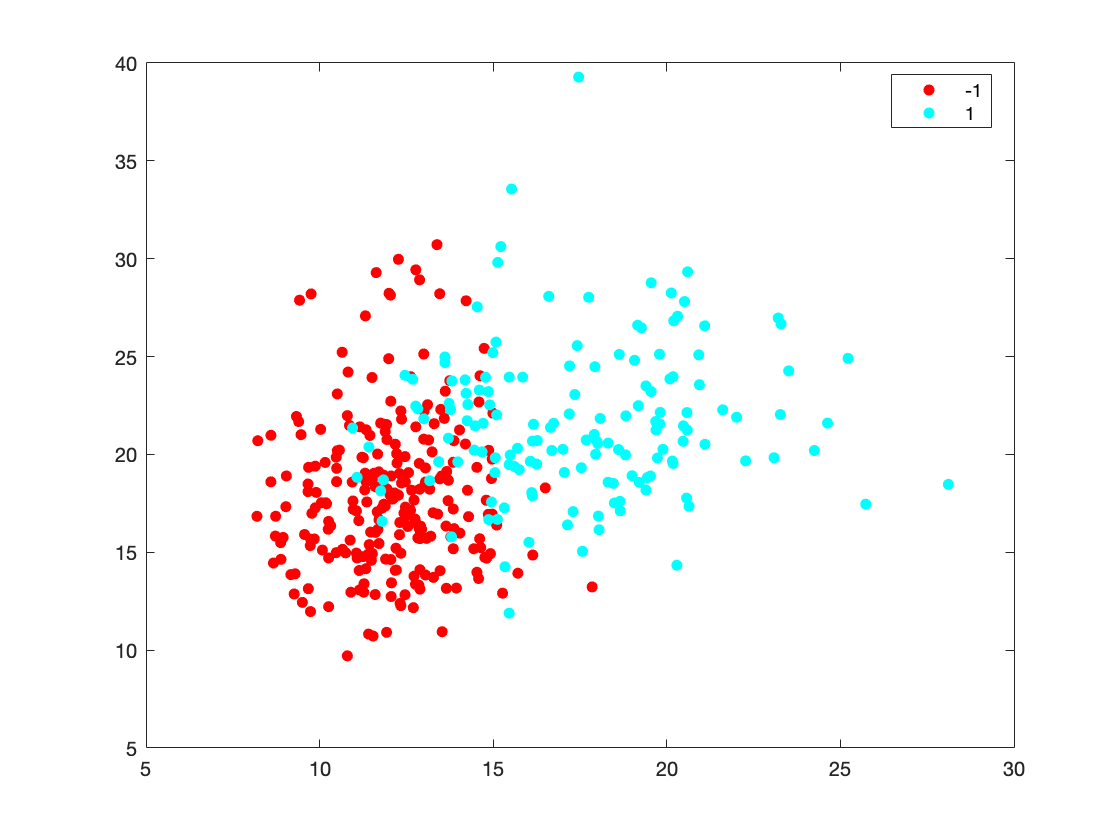

breastDat = load('breast.mat');
gscatter(breastDat.trainset(:, 1), breastDat.trainset(:, 2), breastDat.labels_train)

This dataset has a large number of input dimensions and is clearly not linearly separable. An RBF model is thus again a good first candidate. Unfortunately the dimensionality deprives us of the ability to visualise the decision boundary.

[breastModel, breastYest, breastYlatent] = RBFModelBuilder(breastDat.trainset, breastDat.labels_train, breastDat.testset);


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         44.7376
                                          [sig2]        48.1517
                                          F(X)=         0.015
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   44.7376      48.1517

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     1.500000e-02     3.8008        3.8744      initial 
     2           5     1.500000e-02     3.8008        3.8744      contract outside 
     3           7     1.500000e-02     3.8008        3.8744      contract inside 
     4           9     1.500000e-02     3.8008        3

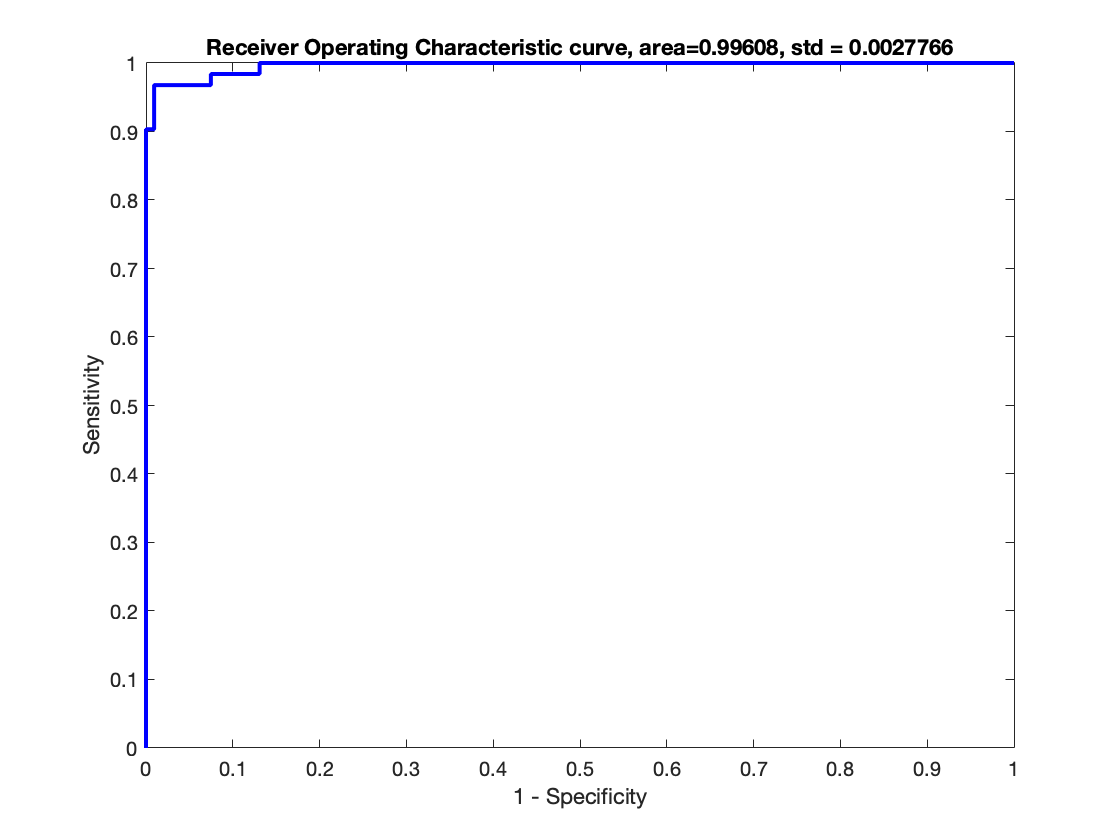

ans = 0.9961

roc(breastYlatent, breastDat.labels_test)

This seems like an excellent classifier.

## LS-SVM classifier - Diabetes example

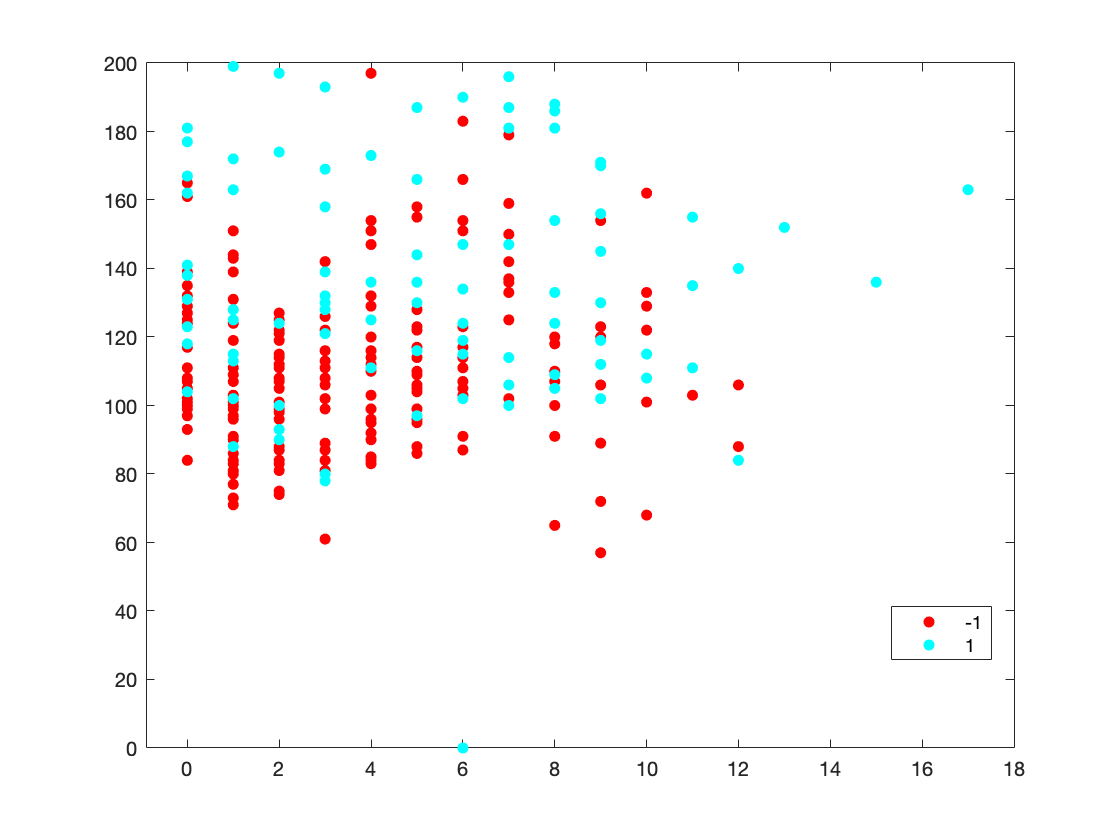

diabetesDat = load('diabetes.mat');
gscatter(diabetesDat.trainset(:, 1), diabetesDat.trainset(:, 2), diabetesDat.labels_train)

This dataset is also not linearbly separable. Interesingly, one of the features is ordinal.

[diabetesModel, diabetesYest, diabetesYlatent] = RBFModelBuilder(diabetesDat.trainset, diabetesDat.labels_train, diabetesDat.testset);


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.78545
                                          [sig2]        45.4407
                                          F(X)=         0.24
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.785448      45.4407

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     2.400000e-01     -0.2415        3.8164      initial 
     2           5     2.400000e-01     -0.2415        3.8164      contract outside 
     3           6     2.400000e-01     -0.2415        3.8164      reflect 
     4           8     2.400000e-01     -0.2415        3.816

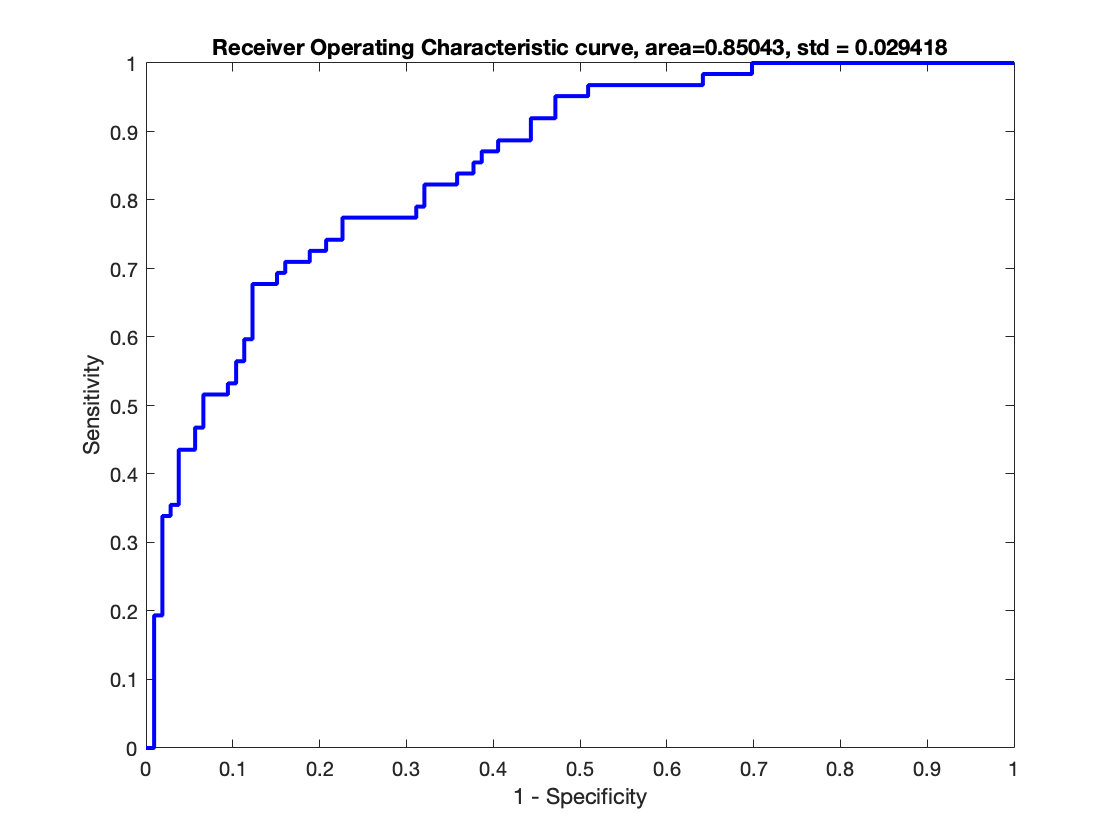

ans = 0.8504

roc(diabetesYlatent, diabetesDat.labels_test)

This is still a very good model, but the performance reflects the complexity of the dataset.

function [trainedModel, Yest, Ylatent] = RBFModelBuilder(Xtrain, Ytrain, Xtest)
[gamSimp, sigSimp, costSimp] = tunelssvm({Xtrain, Ytrain, 'c', ...
    [], [], 'RBF_kernel'}, 'simplex', 'crossvalidatelssvm', {10, 'misclass'});
modelSpec= {Xtrain, Ytrain, 'c', gamSimp, sigSimp, 'RBF_kernel'};
trainedModel = trainlssvm(modelSpec);
[Yest, Ylatent] = simlssvm(modelSpec, {trainedModel.alpha, trainedModel.b}, Xtest);
end